## 线性回归

数据模型明确描述了预测变量和响应变量之间的关系。

- 线性回归拟合一个在模型系数上是线性的数据模型。

- 我们将要：

- 使用 ``运算符执行简单线性回归。

- 使用相关性分析来确定两个量是否相关，以证明拟合数据的合理性。

- 将线性模型拟合到数据。

- 通过绘制残差图并寻找模式来评估拟合优度。

- 计算拟合优度度量  $R^2$ 和调整后的 $R^2$ 

### 简单线性回归

线性回归模拟因变量（或响应变量）$y$与一个或多个自变量（或预测变量） $x_1$,..., $x_n$�之间的关系。简单线性回归只考虑一个自变量，使用以下关系：


$$y=\beta_0 +\beta_1 x+\in$$


 • 其中$\beta_0$�是 $y$ 截距，$\beta_1$�是斜率（或回归系数），*ϵ*是误差项。

• 对于数据集：Y = XB

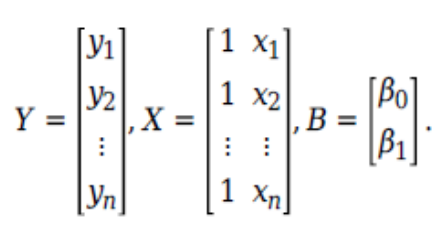

• 从数据集 `accidents`中，将事故数据加载到 `y`中，将州人口数据加载到 `x`中。

•   使用 \运算符找出一个州的事故数与州人口之间的线性回归关系 y = $\beta_1 +x$。

• \运算符执行最小二乘回归。

load accidents

b1 =      1.372716735564871e-04


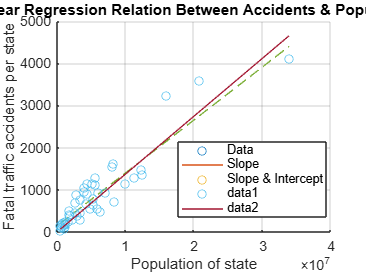

x = hwydata(:,14); % 各州人口
y = hwydata(:,4); % 每个州的事故数
format long
b1 = x\y


yCalc1 = b1*x;
scatter(x,y)
hold on

plot(x,yCalc1)
xlabel('Population of state')
ylabel('Fatal traffic accidents per state')
title('Linear Regression Relation Between Accidents & Population')
grid on




通过在你的模型中包含一个 y 截距  $\beta_0$来改进拟合，即$y=\beta_0 +\beta_1 x$。通过给 `x`添加一列 1 并使用 \运算符来计算 $\beta_0$。

load accidents

b1 =      1.372716735564871e-04


x = hwydata(:,14); % 各州人口
y = hwydata(:,4); % 每个州的事故数
format long
b1 = x\y

yCalc1 = b1*x;
scatter(x,y)
hold on
plot(x,yCalc1)
xlabel('Population of state')
ylabel('Fatal traffic accidents per state')
title('Linear Regression Relation Between Accidents & Population')

b = 1.0e+02 *

   1.427120171726538
   0.000001256394274


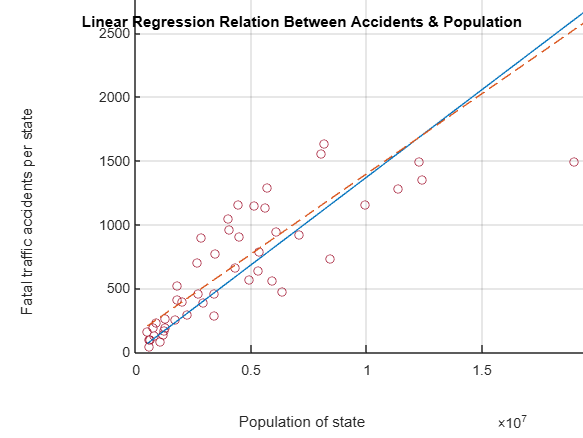

grid on

X = [ones(length(x),1) x];

b = X\y
yCalc2 = X*b;
plot(x,yCalc2,'--')
legend('Data','Slope','Slope & Intercept','Location','best');

% 计算 yCalc1 和 yCalc2 的 R^2
% 计算 ycalc1 的 R 平方
SS_res1 = sum((y - yCalc1).^2); % 残差平方和
SS_tot1 = sum((y - mean(y)).^2); % 总平方和
R_squared1 = 1 - (SS_res1 / SS_tot1); % ycalc1 的 R 平方

% 计算 ycalc2 的 R 平方
SS_res2 = sum((y - yCalc2).^2); % 残差平方和
SS_tot2 = sum((y - mean(y)).^2); % 总平方和

R-squared for ycalc1: 0.8222


R_squared2 = 1 - (SS_res2 / SS_tot2); % ycalc2 的 R 平方

R-squared for ycalc2: 0.8382



% 显示结果
fprintf('R-squared for ycalc1: %.4f\n', R_squared1);
fprintf('R-squared for ycalc2: %.4f\n', R_squared2);


### 残差与拟合优度

•

- 残差是响应（因）变量的观测值与模型预测值之间的差异。

- 使用线性模型生成拟合需要最小化残差的平方和。这种最小化产生了所谓的最小二乘拟合。

- 拟合优度的一个度量是决定系数，或称  $R^2$


$$R^2 =1-{\textrm{SS}}_{\textrm{resid}} \;/\;{\textrm{SS}}_{\textrm{total}}$$


•${\mathrm{SS}}_{\mathrm{resid}}$是回归的残差平方和。

•${\textrm{SS}}_{\textrm{total}}$是因变量与均值的偏差平方和（总平方和）。

***问题：在之前的练习中计算 R 平方。***

### 多项式回归

• *polyfit *可用于计算从 *x*预测 *y*的线性回归。

• `p = polyfit(x,y,n)`返回阶数为 *n*的多项式 *p*(*x*)的系数，该多项式是与 *y*中数据最佳拟合（在最小二乘意义上）的。

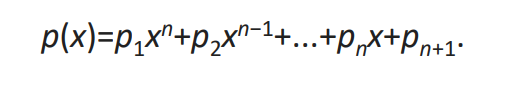

• 线性拟合的阶数为 1，二次拟合为 2，三次拟合为 3，依此类推。 

### 多项式回归的调整后  $R^2$ 

对于更高阶的多项式。当添加更多项时，你会增加决定系数 $R^2$。你能获得与数据更接近的拟合，但代价是模型更复杂，而 $R^2$无法解释这一点。

- 调整后的 $R^2$�确实包含了对模型中项数的惩罚。

• *d*是多项式的次数。

• *n*是数据点的数量。

课堂练习：比较线性拟合、二次拟合、三次拟合。计算 $R^2$和调整后的$R^2$。

load count.dat
x = count(:,1);
y = count(:,2); 